clc
clear

dataset_dir = 'F:\RESEARCH\Data7\FLIR\Dataset\video sample\tif\';
index = 183;

## normalize

im1 = read_image(index, dataset_dir, true);

Rec-000020 - Copy - test_183.tif


im1_woBg = removeBackground(im1);

sensitivity = 0.4

sensitivity = 0.4000

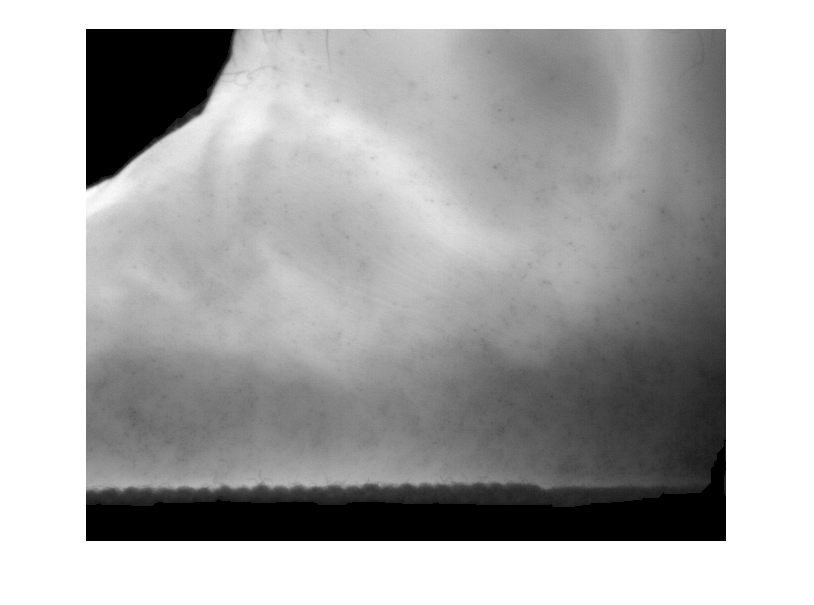

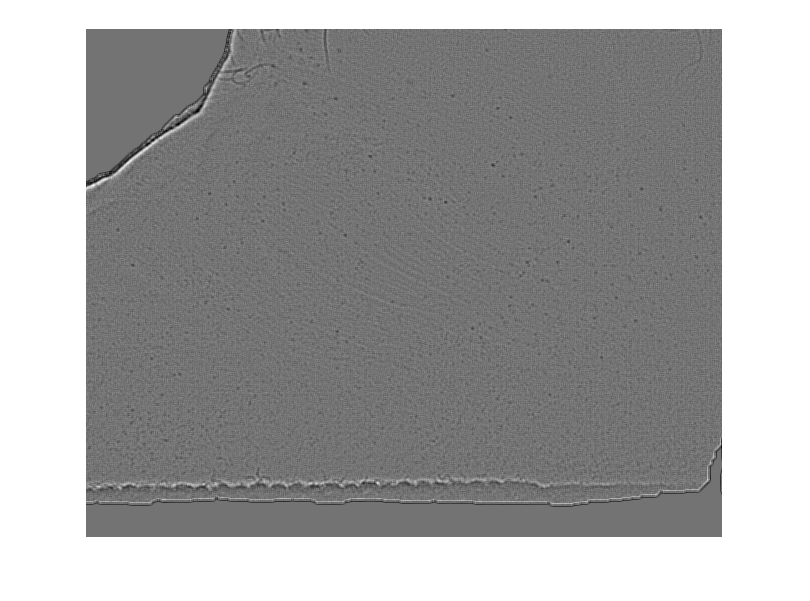

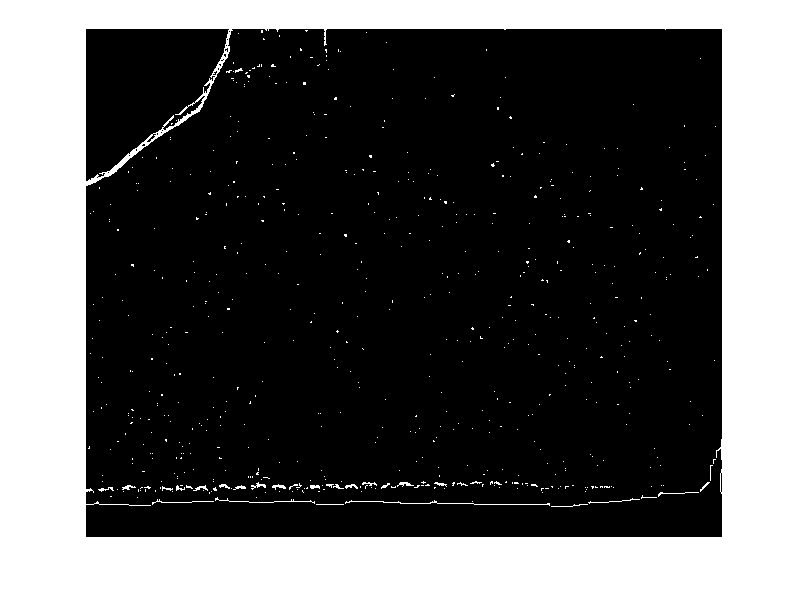

Error using linkaxes (line 79)
There must be at least one valid axes.

Error in method_development>myshow (line 37)
    linkaxes(ax)

[im_filtered, candidates1] = apply_filter(im1_woBg,0.4);

myshow('separate','imshow',im1_woBg, im_filtered, candidates1)

% myshow('imtool',im_filtered)

im_filtered_suppressed = imhmax(im_filtered,0.4);

candidates2 = ~imbinarize(im_filtered_suppressed,'adaptive','ForegroundPolarity','dark','Sensitivity',sensitivity);

% watershed_output = watershed(im_filtered_suppressed,4);

% myshow('imtool',im1, im_filtered_suppressed, candidates2)

% candidates1_watershed = keeping_the_watershed_area(watershed_output, candidates1);
% candidates2_watershed = keeping_the_watershed_area(watershed_output, candidates2);

% myshow('imshow',candidates2, candidates2_watershed)

function myshow(separate_joined,mode,varargin)
    for x = 1:length(varargin)
        
        if strcmp(separate_joined,'joined')
            if strcmp(mode,'imshow')
                ax(x) = subplot(1,length(varargin),x); imshow(varargin{x},[]);
            elseif strcmp(mode,'imtool')
                ax(x) = subplot(1,length(varargin),x); imtool(varargin{x},[]);
            end
        else
            figure, 
            ax(x) = imshow(varargin{x},[]);
        end

    end
    linkaxes(ax)

end

function im1_woBg = removeBackground(im1)
    im1b = im1*0;
    im1b(im1 < 0.1) = 1;
    im1b = imclose(im1b,strel('disk',20));
    
    im1_woBg = im1;
    im1_woBg(im1b==1) = 0;
    
    im1_woBg = func_normalize(im1_woBg - 0.1, 1);
    
end

function im = read_image(index, dataset_dir, normalize)
    
    % dir = 'F:\Datasets\FLIR\video sample\tif\';
    name = ['Rec-000020 - Copy - test_',int2str(index),'.tif'];
    disp(name)
    Dirr = [dataset_dir, name];
    im = imread(Dirr);
    
    if normalize
        im = func_normalize(im,1);
    end

end

function im = func_normalize(im,type)
    mn = min(im(:));
    mx = max(im(:));
    if type == 16
        im = uint16(  (im-mn)*(2^16)/(mx-mn)  );
    elseif type == 8
        im = uint8(  (im-mn)*(2^8)/(mx-mn)  );
    elseif type == 1
        im = (im-mn)/(mx-mn);        
    end
    
    % im1c = histeq(im1_woBg,50);
    % im2 = adaptthresh(im1,'NeighborhoodSize',[3,3], 'ForegroundPolarity','dark', 'Statistic','median');
    
end

function [im1d, im1d_binarize] = apply_filter(im1_woBg,sensitivity)
    % local differentiation
    h = [-1,-1,-1;-1,8,-1;-1,-1,-1];
    im1c = filter2(h,im1_woBg,"valid");
    im1c = func_normalize(im1c, 1);
    
    % local average
    h = ones(3,3)/4;
    im1d = filter2(h,im1c,"valid");
    im1d = func_normalize(im1d, 1);
    
    im1d_binarize = ~imbinarize(im1d,'adaptive','ForegroundPolarity','dark','Sensitivity',sensitivity);
end

function mask = keeping_the_watershed_area(watershed_output, binary_mask)
    mskk = watershed_output;
    mskk(binary_mask == 0) = 0;
    c = unique(mskk(:));
    c(c == 0) = [];
    
    obj = regionprops(watershed_output,'Area','PixelIdxList');
    
    mask = watershed_output*0;
    for i = 1:length(c)
        mask(obj(c(i)).PixelIdxList) = c(i);
    end
end